Jesus Molina Roldan

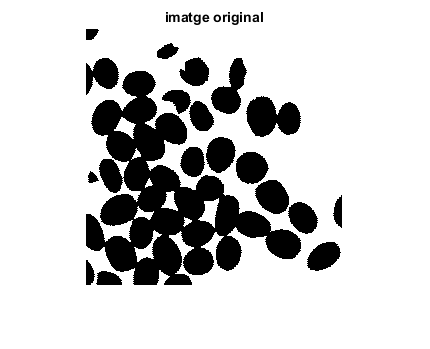

clear
bw = imread('cafe.tif'); 
bw(bw>0) = 255;
imshow(bw), title('imatge original');

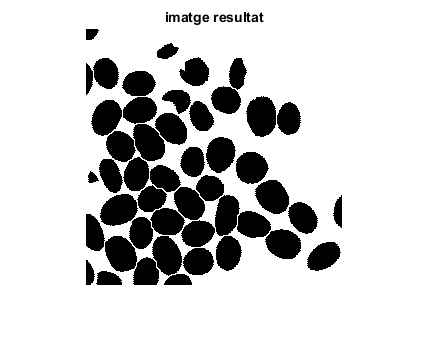


D = -bwdist(bw);

mask = imextendedmin(D,2);

D2 = imimposemin(D,mask);

Ld2 = watershed(D2);


bw(Ld2 == 0) = 255;

imshow(bw), title('imatge resultat');